# Jackie's Code Experimenting with Occupancy Grid

clc                     % clear command window
clear                   % clear MATLAB workspace
format long             % displays decimals in long


**CREATE GLOBAL VARIABLES**

load final_waypoints.mat  %this will be loaded in as the variable "waypoints"

% sampleTime = 0.5;                                  % Sample time [s]
% t = 0:sampleTime:100;                              % Time array
% r = rateControl(1/sampleTime);                     % reset control loop  rate
roverMetersPer5Secs = 2                        % 42 NOTE: DID WE REMEMBER THE ONE WE CALCULATED RIP

roverMetersPer5Secs =      2


% reset(r);                                          % reset loop time to zero


**CREATE MISSION DEFINITION FILE**

% Build list of desired behaviors for Mission 1
MDFOne = table(waypoints(:,1),waypoints(:,2));      % Build Mission Definition File (MDF) table

**CREATE NEW OCCUPANCY GRID WITH ADJUSTED GRID SIZE**

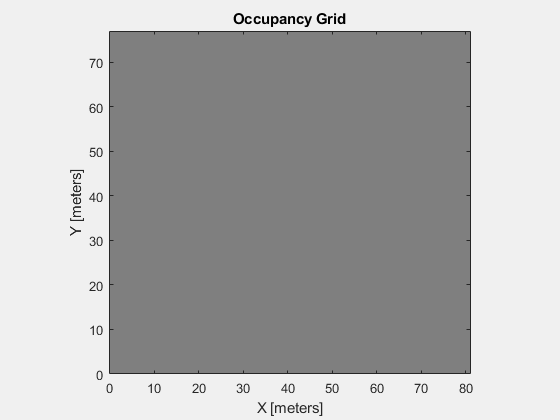

clf
res = 10; % resolution in cells per meter, so there are 10*10 = 100 cells in one meter
gridsize = [81 77];
roverOccupancyGrid = occupancyMap(gridsize(1), gridsize(2), res);

% Create free floating figure (Rover occupancy grid)
figureRoverOccupancy = figure('name', 'RoverOccupancyGrid', 'NumberTitle', 'off', 'Visible', 'on');
figure(figureRoverOccupancy);                            
    show(roverOccupancyGrid); 

**TEST PLOTTING ONE GPS POINT**

Note: all testing done by setting value to 1 because inflate only works on values of 1

GPS_Point =  [42.293252 -71.264429];
gridCoord = GPSToGrid(GPS_Point)

gridCoord =   -0.382946134730265  13.477153738833447


updateOccupancy(roverOccupancyGrid,[gridCoord(1),gridCoord(2)],1);
inflate(roverOccupancyGrid, 1); % NOTE: inflates only values at 1
figure(figureRoverOccupancy);                            
    show(roverOccupancyGrid);

**PLOTTING ALL WAYPOINTS ON NEW OCCUPANCY GRID USING GPSTOGRID FUNCTION**

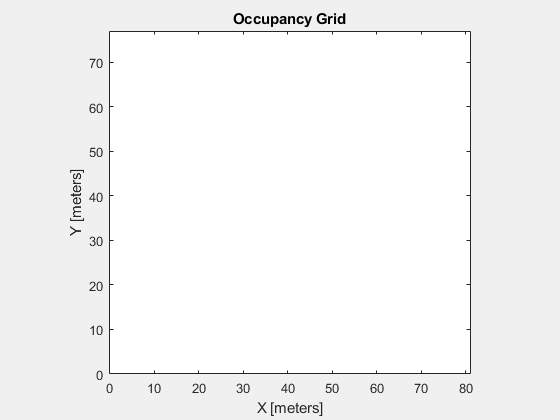

% plot waypoints by setting color as 1
p = 1;
for i = 1:length(waypoints)
    gridCoord = GPSToGrid(waypoints(i,:));
    updateOccupancy(roverOccupancyGrid,[gridCoord(1), gridCoord(2)],1);
end
inflate(roverOccupancyGrid, 1); % helps waypoints show up better

% Create free floating figure (Rover occupancy grid)
figure(figureRoverOccupancy);                            
    show(roverOccupancyGrid);

**CREATE NEW OCCUPANCY GRID WITH ADJUSTED GRID SIZE**

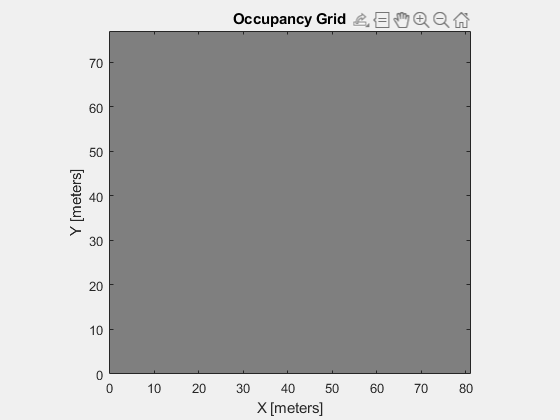

clf
res = 10; % resolution in cells per meter, so there are 10*10 = 100 cells in one meter
gridsize = [81 77];
roverOccupancyGrid = occupancyMap(gridsize(1), gridsize(2), res);

% Create free floating figure (Rover occupancy grid)
figureRoverOccupancy = figure('name', 'RoverOccupancyGrid', 'NumberTitle', 'off', 'Visible', 'on');
figure(figureRoverOccupancy);                            
    show(roverOccupancyGrid); 

**TESTING WITH ONE WAYPOINT**

testing rover going from first waypoint to 2nd waypoint

% start rover at first waypoint
roverLocation = waypoints(1,:);
roverLocation_grid = GPSToGrid(roverLocation)

roverLocation_grid =    4.235338213895992  17.142767153459943


updateOccupancy(roverOccupancyGrid,[roverLocation_grid(1), roverLocation_grid(2)],1);


% go to the second waypoint
targetWaypoint = waypoints(2,:);
targetWaypoint_grid = GPSToGrid(targetWaypoint)

targetWaypoint_grid =    3.658049223799370  23.807516247336000


updateOccupancy(roverOccupancyGrid,[targetWaypoint_grid(1), targetWaypoint_grid(2)],1);

inflate(roverOccupancyGrid, 1); % helps waypoints show up better
% Create free floating figure (Rover occupancy grid)
figure(figureRoverOccupancy);                            
    show(roverOccupancyGrid);
    
    
% global bearing
roverBearing = 330;

% distance between location and waypoint in meters
distToTargetMeters = norm(roverLocation_grid-targetWaypoint_grid)

distToTargetMeters =    6.689704258217138


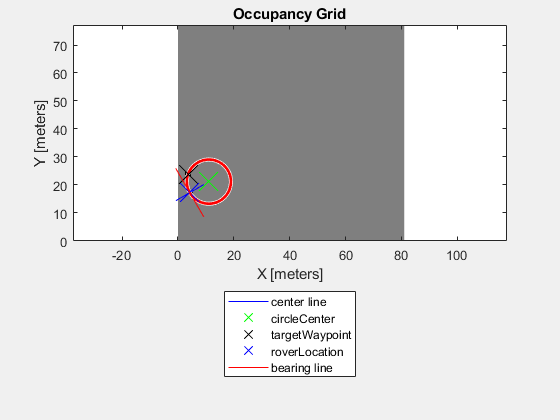

m =   -1.732050807568877


b =   24.478588127165821


pt_on_line =    0.387443530465335


turn_direction = "CW"

newRoverLocation =    3.345823132537837  19.468015051189166


distToTargetMeters =    4.350718993847368


m =   -1.732050807568877


b =   25.263150709883959


pt_on_line =    0.840410948793760


turn_direction = "CW"

newRoverLocation =    3.224098871767919  21.954618773175802


distToTargetMeters =    1.903034933409647


m =   -1.732050807568877


b =   27.538921827703334


pt_on_line =    2.154328016280751


turn_direction = "CW"

newRoverLocation =    3.882254134817988  24.355628251619663


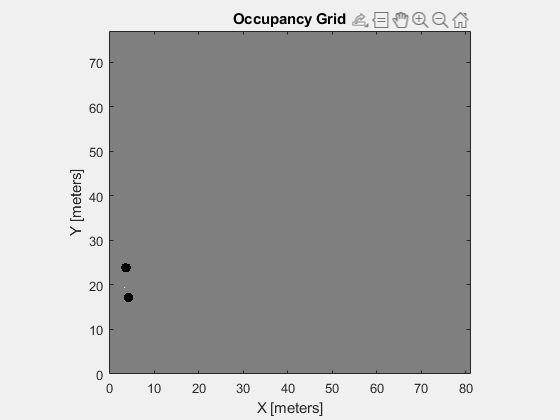

distToTargetMeters =    0.592194741081615



New_Rover_Location = [];

dist_threshold = 1; %meters
count = 0;   
[circle_center,radius] = findCircle(roverLocation_grid, targetWaypoint_grid, roverBearing);

while distToTargetMeters > dist_threshold && count < 10

   [roverLocation_grid] = GoToWayPoint(roverOccupancyGrid, figureRoverOccupancy, targetWaypoint_grid, roverBearing, roverLocation_grid, roverMetersPer5Secs, New_Rover_Location, circle_center,radius);
   distToTargetMeters = norm(roverLocation_grid-targetWaypoint_grid)
   count = count+1;
end

**JACKIE'S FUNCTIONS**

all math for this function done in meters

function [roverLocation] = GoToWayPoint(roverOccupancyGrid,figureRoverOccupancy, targetWaypoint, roverBearing, roverLocation, roverMetersPer5Secs, New_Rover_Locations, circle_center,radius)
    
    %    Initialize the waypoint vector
    waypointSteeringVector = zeros(71,1);
    
    % Do math to find radius of bumblebee circle -> put in function
    time_elapsed = 1;   % experimenting with 1 second driving intervals
    
    
    [m, b] = find_bearing_line(roverLocation, roverBearing)
    % have other fucntion that takes line and waypoint and output clockwise
    % or counterclockwise
    
    [turn_direction] = CW_or_CCW(targetWaypoint, m, b)
    
    [newRoverLocation] = updateRoverPosition(roverLocation, circle_center, radius, time_elapsed, turn_direction)
    
    updateOccupancy(roverOccupancyGrid, [newRoverLocation(1) newRoverLocation(2)], 0);

    roverLocation = newRoverLocation;
    
    figure(figureRoverOccupancy);
        show(roverOccupancyGrid); 
        
    % TODO: output steering angle
end

function [circle_center, radius] = findCircle(roverLocation, targetWaypoint, roverBearing)   
    %% find the equation of the circle given line and two points
    
    % find the equation of the line that i
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    [m, c] = find_line(roverLocation, roverBearing);
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %y =  mx +  c
    %ax + by +  d = 0
    %mx - y +   c = 0
    a = m;
    b = -1;
    d = c;
    
    % equation of a circle
    % x2+y2+2gx+2fy+c=0 (-g,-f) is the center
    x1 = roverLocation(1); y1 = roverLocation(2);
    x2 = targetWaypoint(1); y2 = targetWaypoint(2);
    syms g f c
    eqn1 = x1^2 + y1^2 + 2*g*x1 + 2*f*y1 + c == 0;
    eqn2 = x2^2 + y2^2 + 2*g*x2 + 2*f*y2 + c == 0;
    
    % substitute g and f into the equation of the line
    eqn3 = a*-g + b*-f + d == 0;
    
    % solving the three equations
    sol = solve([eqn1, eqn2, eqn3], [g, f, c]);
    G = sol.g;
    F = sol.f;
    C = sol.c;
    
    % assigning the circle center
    circle_center = double([-G, -F]);
    
    % finding the radius
    radius = norm(circle_center - roverLocation);
    
    % sanity check to make sure its passing throught the points
    % this should be 0
    radius - norm(circle_center - targetWaypoint);
    
    %plotting
    hold on
        viscircles(circle_center,radius);
        plot(circle_center(1),circle_center(2),'gx',"MarkerSize",20, 'DisplayName','circleCenter')
        plot(targetWaypoint(1),targetWaypoint(2),'kx','MarkerSize',20, 'DisplayName','targetWaypoint')
        plot(roverLocation(1),roverLocation(2),'bx','MarkerSize',20, 'DisplayName', "roverLocation")
    hold off
    legend("Location", 'southoutside')
    axis equal
end

function [m, b] = find_line(roverPosition, roverBearing)
    % if robot bearing pointing in quad I and III
    x = roverPosition(1);
    y = roverPosition(2);
    if ((roverBearing > 0 && roverBearing < 90) ||(roverBearing > 180 && roverBearing < 270))
%         disp("quad 1 3")
        omega = mod(roverBearing+90, 90);
        omega = 90 - omega
        a = abs(y*tand(omega));
        x_int = a+x;
    elseif ((roverBearing > 90 && roverBearing < 180) ||(roverBearing > 270 && roverBearing < 360))
%         disp("quad 2 4")
        omega = mod(roverBearing+90, 90);
        a = abs(y*tand(omega));
        x_int = x-a;
    end
    m = (y-0)/(x-x_int);
    b = y-m*x;

    % plotting
%     
    hold on
    x= linspace(x-5,x+5, 10);
    y= m*x + b;
    
    plot(x, y, 'b', 'DisplayName','center line')
    axis equal
    hold off
end

function [m, b] = find_bearing_line(roverPosition, roverBearing)
    % if robot bearing pointing in quad I and III
    x = roverPosition(1);
    y = roverPosition(2);
    omega = mod(roverBearing, 90);

    if ((roverBearing > 0 && roverBearing < 90) ||(roverBearing > 180 && roverBearing < 270))
%         disp("quad 1 3")
        a = abs(y*tand(omega));
        x_int = x-a;
    elseif ((roverBearing > 90 && roverBearing < 180) ||(roverBearing > 270 && roverBearing < 360))
%         disp("quad 2 4")
        omega = 90-omega;
        a = abs(y*tand(omega));
        x_int = x+a;
    end
    m = (y-0)/(x-x_int);
    b = y-m*x;
    
    hold on
    x= linspace(x-5,x+5, 10);
    y= m*x + b;
    
    plot(x, y, 'r', 'DisplayName','bearing line')
    axis equal
    hold off

end

function [direction] = CW_or_CCW(targetWaypoint, m, b)
    pt_on_line = (targetWaypoint(2) - b)/m % x coord of point of projected waypoint on rover bearing line
    if pt_on_line < targetWaypoint(1)
        direction =  "CW";
    else
        direction =  "CCW";
    end
end


function [newRoverPosition] = updateRoverPosition(roverPosition_grid, circle_center, radius, time_elapsed, turn_direction)
    % find the location of the rover if we're rotating counterclockwise using this link:
        % https://math.stackexchange.com/questions/53875/calculating-point-around-circumference-of-circle-given-distance-travelled

    speed = 2.5; %m/s
    dist_traveled = speed*time_elapsed;
    
    % TODO: figure out whether we're traveling clockwise or counterclockwise
    
    %center
    a = circle_center(1);
    b = circle_center(2);
    
    %current location of of rover
    x = roverPosition_grid(1);
    y = roverPosition_grid(2);
    r = radius;
    
    if turn_direction == "CCW"
        phi = dist_traveled/r;
    elseif turn_direction == "CW"
        phi = -dist_traveled/r;
    end
    
    newRoverPosition(1) = a+(x-a)*cos(phi) - (y-b)*sin(phi);   % circle math in radians
    newRoverPosition(2) = b+(x-a)*sin(phi) + (y-b)*cos(phi);
end


function [gridCoordinate] = GPSToGrid(GPSCoordinate)
    altitude = 10;
    % origin is at the bottom left corner
    origin = [42.29313067072105, -71.26442435650652, altitude];
    [gridCoordinate(1),gridCoordinate(2)] = latlon2local(GPSCoordinate(1), GPSCoordinate(2),altitude,origin);
end

% TODO: Methods to try to find bearing
%     bearing = ((1/radius_meters)-0.05312)/0.03153;
%     bearing = bearing - 3;
%     if bearing < 0
%         bearing = 0;
%     end

    
    % converting to bearing
%     bearing = (radius_meters - 3.1595)./(-0.0702)
%     a = .23;
%     b = 0.42;
%     c = .21;
%     bearing = asind((2*b)/(2*radius_meters+a+c))
%     if radius_meters > 30
%             bearing = 0;
%         elseif radius_meters > 20
%             bearing = 0;
%     elseif 
%         elseif radius_meters > 2.73
%             bearing = 1;
%     end
%      
    % finding the index for the turn angles to change
%      bearing = (round(bearing))
%      turnAngles = -35:1:35; % 8 vectors( y range is from -1 to 1)
%      ind = find(abs(turnAngles - bearing) <= 0.001);
% 
%     % Change the steering vector
%     waypointSteeringVector(ind) = 0.5;
% end

function[roverOccupancyGrid, roverBearing, roverLocation] = GPSGetLocation(roverOccupancyGrid, neo) % this will be provided from canvas
    basic_data = neo.getBasic();
    % roverX = basic_data.longitude
    % roverY = basic_data.lattitude
    roverLocation = [basic_data.longitude basic_data.lattitude];
    roverBearing = basic_data.heading;
    % plotting rover position on occupancy grid through conversion
%     [gridIndex] = GPSCoordToGridIndex(GPSCoordinate);
%     pvalues = 0.6; % this is the value for the rover position
%     updateOccupancy(roverOccupancyGrid,[gridIndex(1) gridIndex(2)],pvalues);
end

function [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1, adcDevice2)
     rawRangeData1 = SENSE_ADC(adcDevice1);
     rawRangeData2 = SENSE_ADC(adcDevice2);
     rawRangeData = [rawRangeData2(1:3),rawRangeData1(1:2)];
     angles = [1 2 3 4 5; -pi/3 -pi/6 0 pi/6 pi/3]; % chagne this later     
     threshold = 40;
     for i = 1:5
        % voltage to distance     
        distance = (rawRangeData(i) - 2.805)/(-0.03316);
        if distance < threshold
            [obstaclePosX, obstaclePosY] = findGridPos(angles(i), distance, roverLocation);
            updateOccupancy(roverOccupancyGrid, [obstaclePosX obstaclePosY], 0.1)
        end   
     end  
end


function [obstaclePosX, obstaclePosY] = findGridPos(omega, distance, roverLocation) % Helper function for sonar / IR
    if omega < 0
            omega = 360+omega;
    elseif omega > 360
        omega = omega-360;
    end
    quo = omega/90;
    modulo = mod(omega,90);
    if floor(quo) == 0 % Quadrant I
        obstaclePosX = roverLocation(0) + (distance*cosd(modulo))
        obstaclePosY = roverLocation(1) + (distance*sind(modulo))
    elseif floor(quo) == 1 % Quadrant IV
        obstaclePosX = roverLocation(0) + (distance*cosd(modulo))
        obstaclePosY = roverLocation(1) - (distance*sind(modulo))
    elseif floor(quo) == 2 % Quadrant III
        obstaclePosX = roverLocation(0) - (distance*cosd(modulo))
        obstaclePosY = roverLocation(1) - (distance*sind(modulo))
    elseif floor(quo) == 3 % Quadrant IV
        obstaclePosX = roverLocation(0) - (distance*cosd(modulo))
        obstaclePosY = roverLocation(1) + (distance*sind(modulo))
    end
end

function [roverOccupancyGrid] = SonarRange(roverOccupancyGrid, figureRoverOccupancy, headBearing, roverLocation, adcDevice1) % fill in other variables
% Mark obstacles based on the positions on the grid

    % Sonar calibration, covert voltage data into distance measurement (cm)
    distanceLeft = (adcDevice1.readVoltage(2)-0.01063)/0.01584; 
    distanceRight = (adcDevice1.readVoltage(3)-0.01063)/0.01584;
    
    % If measured distance is within some threshold, mark it as an obstacle
    % on the occupancy grid
    threshold = 5;
    if distanceLeft < threshold
        omegaLeft = headBearing-90;
        [obstaclePosX, obstaclePosY] = findGridPos(omegaLeft, distanceLeft, roverLocation)
        updateOccupancy(roverOccupancyGrid, [obstaclePosX obstaclePosY], 0.1)
        
    end
    if distanceRight < threshold 
        omegaRight = headBearing-90;
        [obstaclePosX, obstaclePosY] = findGridPos(omegaRight, distanceRight, roverLocation)
        updateOccupancy(roverOccupancyGrid, [obstaclePosX obstaclePosY], 0.1)
    end
end



function[roverOccupancyGrid] = MissionOneSense(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1,adcDevice2, robotCam,roverJoy, roverServos)
%% TODO for sonar function, headBearing == roverBearing + (panAngle converted to global bearing)
    
    joystickControl=1
    while joystickControl == 1
        % Use joystick to move rover head, Y + enter when ready to sense
        while 1
            [panAngle, tiltAngle] = SENSE_JoyStick(roverJoy)
            DrivePanTilt(panAngle, tiltAngle, roverServos)
            stop=input('Ready to sense? type Y then hit enter ','s');
            if stop == 'Y'
                break
            end
        end
        % Call all the sense functions related to Mission 1
        [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, adcDevice1, adcDevice2) % fill in other variable
%         [roverOccupancyGrid] = PiCamLaser(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, robotCam) % laser for obstacle avoidance
%         [roverOccupancyGrid] = PiCamObstacles(roverOccupancyGrid, figureRoverOccupancy, roverBearing, roverLocation, robotCam) % color masking for obstacles
        [roverOccupancyGrid] =  SonarRange(roverOccupancyGrid, figureRoverOccupancy, roverBearing+panAngle, roverLocation, adcDevice1) % fill in other variables
       
        figure(figureRoverOccupancy);     % Show updated occupancy grid
            hold on;
            show(roverOccupancyGrid);
            grid on;
            grid minor;
            hold off;
        
        joystickControl=input('Keep sensing? (0-1)');
    end
end


function [panAngle, tiltAngle] = SENSE_JoyStick(roverJoy)
% this function polls USB joystick and returns x position 
% for Rover steering angle and y position for Rover velocity
    stickX = axis(roverJoy, 1);     % X-axis is joystick axis 1 (-1 to 1)
    stickY = axis(roverJoy, 2);     % Y-axis is joystick axis 2 (-1 to 1)
    panAngle = 50 + (10 * stickX);  % scale X for servo with pulse centered at 50
    tiltAngle = 50 + (-10 * stickY);  % scale Y for servo with pulse centered at 50
end

function rawRangeDataN = SENSE_ADC(adcDeviceN)
     % read ADC1 Pin 0-4 voltage
    rawRangeDataN = [adcDeviceN.readVoltage(0), adcDeviceN.readVoltage(1), ...
                adcDeviceN.readVoltage(2), adcDeviceN.readVoltage(3)]; 
end

**THINK FUNCTIONS**


function [steeringAngle] = roverArbiter(behavior1, behavior2, behavior3, behavior4, behavior5)
% From all the brainwaves generated from the different behaivoursav, output a final direction
    
    % If parameters are not given, default as vector of zeros
    num_behaviors = 5;
    switch nargin
        case 4
            behavior5 = zeros(1,71);
            num_behaviors = 4;
        case 3
            behavior4 = zeros(1,71);
            behavior5 = zeros(1,71);
            num_behaviors = 3;
        case 2
            behavior5 = zeros(1,71);
            behavior4 = zeros(1,71);
            behavior3 = zeros(1,71);
            num_behaviors = 2;
        case 1
            behavior5 = zeros(1,71);
            behavior4 = zeros(1,71);
            behavior3 = zeros(1,71);
            behavior2 = zeros(1,71);
            num_behaviors = 1;
    end    
    steeringVector = (behavior1 + behavior2 + behavior3 + behavior4 + behavior5)/num_behaviors;
    
    turnAngles =  -35:1:35; % 8 vectors( y range is from -1 to 1)
    
%     figure(figureArbiter)                 % go to brain waves figure
%     %clf                               % clear figure of old waves
%     plot(turnAngles, behavior1, "b-+");        % plot behaviour 1 waveform
%      ax=gca;
%      ax.XDir = 'reverse';
%     axis([-8 8 -8 8]);
%     grid on;
%     grid minor;
%     hold on
%     plot(turnAngles, behavior2, "g-+");
%     plot(turnAngles, behavior3, "c-o");
%     plot(turnAngles, behavior4, "y-o");
%     plot(turnAngles, behavior5, "b-o");
%     
%     plot(turnAngles, steeringVector, "r-+");       % plot sum of steer angle waveform
%     legend('behavior1','behavior2','behavior3','behavior4','behavior5') % label plot
%     hold off
    
    [x,ind] = max(steeringVector);
    steeringAngle = turnAngles(ind)    
end

function pwm = AngleForServo(angle)
pwm = ((angle + 85.21)/1.755) - .6;
end

function [turn] = leftorright_quad2(roverLocation, roverBearing, waypoint)  
    A = roverLocation;    
    point_x= roverLocation(1) + 2*cosd(roverBearing) % point 2
    point_y = roverLocation(2) + 2*sind(roverBearing)% point2
    B = [point_x point_y];
%     line_eq = k*x + n
%     P = (a,b)
    k = (A(2) - B(2))/(A(1) - B(1));
    n = A(2) - k*A(1);
    
    a = waypoint(1);
    b = waypoint(2);
    
   
    if k*a + n > b
        turn = 'right';
    elseif k*a + n < b
        turn = 'left';
    else
        turn = 'on the line';
    end
end



**ACT FUNCTIONS**

function [] = DrivePanTilt(panAngle, tiltAngle, roverServos)
     roverServos.setServoPWM(4,panAngle);    % commands panning servo
     roverServos.setServoPWM(5,tiltAngle);   % commands tilting servo
end

function [] = DriveRover(roverServos,direction,speed)
     roverServos.setServoPWM(1,direction);    % commands steering servo
     roverServos.setServoPWM(2,speed);    % commands drive speed controller
end

**SETUP PI**

function [robotPi, blinkLED] = RaspPiSetup()
% RaspPiSetup creates and configures a Raspberry Pi to be a simple robot 
% controller. It requires no inputs and returns a rasPi object

% Create a *raspi* object.
%    robotPi = raspi('192.168.16.65', 'pi', 'raspberry');   % lab pi
   robotPi = raspi('192.168.34.15', 'pi', 'raspberry');   % melody pi
 
% There is a user LED on Raspberry Pi hardware that you can turn on and
% off. Execute the following command at the MATLAB prompt to turn the LED
% off and then turn it on again.
   blinkLED = robotPi.AvailableLEDs{1};
end

**SETUP SERVOS**

function [roverServos] = ServoSetup(robotPi)
% Check everything is plugged in on i2c Qwiic bus (should see devices at  servo 0x40, GPS 0x42, ADC 0x48 0x49, Pi 0x70 
scanI2CBus(robotPi)

% Configure Servo pHAT driver board (address 0x40), set servos to null position.
roverServos = I2C_Servo_pHAT(robotPi);
pSteer = 1;                                   % set Steer servo to pin 1
pSpeed = 3;                                   % set Speed servo to pin 3
comSteer = 50;                                % set intial steer command to 0 angle
comSpeed = 50;                                % set intial speed command to 0 speed
roverServos.setServoPWM(pSteer,comSteer);     % Set sterring servo  center position
roverServos.setServoPWM(pSpeed,comSpeed);     % Set Rover speed  zero

% Define joystick ID (if only using 1 joystick, this will likely be '1')
% ID = 1;

% Create joystick variable
% roverJoy=vrjoystick(ID);

% Visualize the test servo commands in robot coordinate system.
% create a new free-standing figure to display the servo data, rover
% at center
localServoPlot=figure('Name','RoverServoSettings (trigger to STOP)','NumberTitle','off','Visible','on');
PlotServoSettings(localServoPlot,comSteer,comSpeed)
end

function [] = PlotServoSettings(localServoPlot,comSteer, comSpeed)
    % Plots Rover's steerig angle and speed on a stand alone figure
    figure(localServoPlot)
    plot(comSteer,comSpeed, 'r*');
    axis([30 70 30 70]);
    grid on;
    grid minor;
    xlabel('Actual Steer Servo Setpoint')
    ylabel ('Actual Speed Servo Setpoint')
    hold on;
    plot(50,50, 'g^');             % plot robot position 
    hold off;  
end


**SETUP PICAM**

function [robotCam] = PiCamSetup(robotPi)
% To create a connection to the V2 Pi Camera
robotCam = cameraboard(robotPi,'Resolution','320x240');

% Fix auto exposure problem , set eposure to work in lab lighting
% set whitebalance to manual too. Auto exposure and white balance drive
% computer vison algorithms crazy by constantly changing
SetUpPiCamera(robotCam);
end

function []= SetUpPiCamera(robotCam)
    % creates and configures an Pi V2 Camera to be a simple robot 
    % vision system. It requires a standard Pi V2 cmaera attached to 
    % your Raspberry piand takes the picam object name as sole input
    % You need to set your cameras unique parameters to optimize picture
    % D. Barrett 2021 Rev A
    % Available resolutions: '160x120', '320x240', '640x480', '800x600', '1024x768', '1280x720', '1920x1080'
    % Available exposure modes: 'auto', 'night', 'nightpreview', 'backlight', 'spotlight', 'sports', 'snow', 
    % 'beach', 'verylong', 'fixedfps', 'antishake', 'fireworks'
    % Available AWB modes: 'off', 'auto', 'sun', 'cloud', 'shade', 'tungsten', 'fluorescent', 
    % 'incandescent', 'flash', 'horizon'
    % Available metering modes: 'average', 'spot', 'backlit', 'matrix'
    % Available image effects: 'none', 'negative', 'solarise', 'sketch', 'denoise', 
    % 'emboss', 'oilpaint', 'hatch', 'gpen', 'pastel', 'watercolour', 'film', 'blur', 'saturation', 'colourswap', 'washedout', 'posterise', 'colourpoint', 'colourbalance', 'cartoon'

    % Fix  exposure set it to respond quickly, set auto whitebalance to off
    robotCam.ExposureMode = 'sports';
    robotCam.AWBMode = 'fluorescent';
end


**SETUP QWIIC ANALOG INPUT**

function [adcDevice1, adcDevice2] = QWIICInputSetup(robotPi)
% create two SparkFun Qwiic Analog Input adc device that are present on i2c
% bus 1 at address 0x48 and at adress 0x49

adcDevice1 = ads1015(robotPi,'i2c-1','0x48'); % 2 sonar sensor and 2 IR
adcDevice2 = ads1015(robotPi,'i2c-1','0x49'); % 3 IR sensors

rawRangeData1 = SENSE_ADC(adcDevice1)
rawRangeData2 = SENSE_ADC(adcDevice2)
rawRangeData = [rawRangeData1,rawRangeData2];  % concatinate ADC raw vectors together
% Visualize the test sensor scan data in robot coordinate system.
% create a new free-standing figure to display the local sensor data, rover
% at center
localSensorPlot=figure('Name','LocalSensorMap','NumberTitle','off','Visible','on');
PlotSensorData(localSensorPlot, rawRangeData);
end

function [] = PlotSensorData(localSensorPlot, rawRangeData)
    % Plots Rover Sensor Data on a standalone figure
    figure(localSensorPlot)
    plot(rawRangeData)
    axis([1 8 0 3.5]);
    grid on;
    grid minor; 
    xlabel('Sensor Station')
    ylabel ('Raw Sensor Voltage')
    hold on;
    plot(4.5,0, 'r*');             % plot robot position 
    hold off;  
end


**SETUP GPS**

function [neo] = GPSSetup(robotPi)
neo = NEO_M8U(robotPi);            % Create a GPS Class Instance
pause(2);                          % Let GPS get up to speed
% returns a struct with fields: longitude, lattitude, roll, pitch, and heading.
end

**SETUP JOYSTICK**

function [roverJoy] = JoystickSetup(joystickID)
 % Create joystick variable
   roverJoy=vrjoystick(ID);
end